Plot Simulataneous Series

60mm irreg waves

% % %Probe series
Fs_probe = 25; %Guages are sampled at 25Hz 
T_probe = 1/Fs_probe;
L_probe = height(CapacitanceData{:, 2})

L_probe = 10454

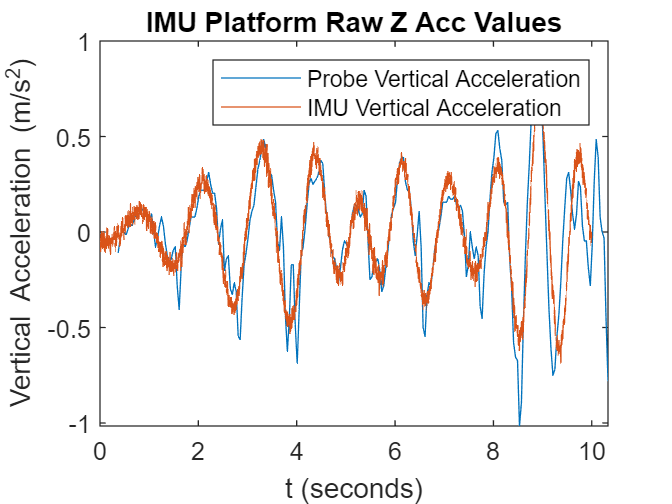

t_probe = (0:L_probe-1)*T_probe-37.15; 

%IMU series
Fs_imu = 500;            % Sampling frequency                    
T_imu = 1/Fs_imu;             % Sampling period       
L_imu = height(IMUData(:, 4));             % Length of signal
t_imu = (0:L_imu-1)*T_imu-410.2;        % Time vector

plot(t_probe(939:939+250-1), probe_1_acceleration(939:939+250-1, 1), t_imu(205101:205101+5000-1), Z_acc_ms2_calibrated(205101:205101+5000-1))
title('IMU Platform Raw Z Acc Values')
legend('Probe Vertical Acceleration','IMU Vertical Acceleration')
xlabel('t (seconds)')
ylabel('Vertical Acceleration (m/s^2)')

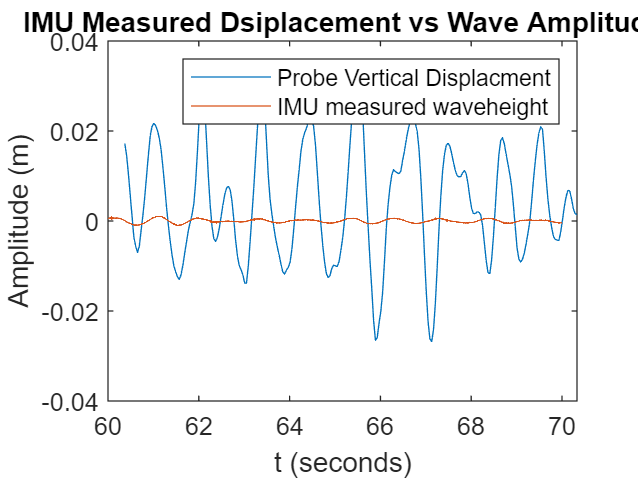


plot(t_probe(939+1500:939+1500+250-1),probe1Height(939+1500:939+1500+250-1, 1), t_imu(205101+30000:205101+30000+5000-1), waveHeightIMU(1+30000:1+30000+5000-1))
title('IMU Measured Dsiplacement vs Wave Amplitude')
legend('Probe Vertical Displacment','IMU measured waveheight')
xlabel('t (seconds)')
ylabel('Amplitude (m)')

20mm irreg waves

% %Probe series
% Fs_probe = 50; %Guages are sampled at 25Hz 
% T_probe = 1/Fs_probe;
% L_probe = height(CapacitanceData{:, 2})
% t_probe = (0:L_probe-1)*T_probe - 31.0; 
% 
% %IMU series
% Fs_imu = 100;            % Sampling frequency                    
% T_imu = 1/Fs_imu;             % Sampling period       
% L_imu = height(IMUData(:, 4));             % Length of signal
% t_imu = (0:L_imu-1)*T_imu-403.5;        % Time vector
% 
% waveHeight = lowpass(waveHeight, 2, 50);
% 
% probe_1_acceleration = lowpass(probe_1_acceleration, 2, 50);
% 
% plot(t_probe, probe_1_acceleration, t_imu, Z_acc_ms2_calibrated)
% title('IMU Platform Raw Z Acc Values')
% legend('Probe Vertical Acceleration','IMU Vertical Acceleration')
% xlabel('t (seconds)')
% ylabel('Vertical Acceleration (m/s^2)')
% 
% plot(t_probe, 2*probe1Height, t_imu(1,40352:164100), waveHeightIMU/2);
% title('IMU Measured Displacement vs Wave Amplitude')
% legend('Probe Vertical Displacment','IMU measured waveheight')
% xlabel('t (seconds)')
% ylabel('Amplitude (m)')
